# verifying Cook–Torrance SRP approximation

Cook–Torrance SRP approximationを数値的なSRP計算と比較して検証

clc
clear
cls

format long

## satelltie configuration

nFacet = 1;
sat.pos = [0 0 0];
thetaN = deg2rad(30);
sat.normal = [0 sin(thetaN) cos(thetaN)];
sat.area = 1;

sat.mCT = 0.2 .* ones(nFacet, 1); % roughness
sat.F0 = 0.5 .* ones(nFacet, 1);
sat.rho = 0.5 .* ones(nFacet, 1);

## parameters

const = orbitConst;
d = au2km(1.0, const) * 10^3; % m, distance from sat to sun
dAU = km2AU(d ./ 10^3, const); % AU
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;

## diffuse (analytic)

太陽定数などの係数を含む値


$${\bf f}_{{\rm SRP},d} = -\frac{S_{0}}{cr^{2}_{\rm AU}} A ({\bf n}^{T}{\bf s}) \int \int ({\bf n}^{T}{\bf v})\frac{\rho}{\pi}\sin{\theta_{r}}{\bf v}\mathrm{d}\theta_{r}\mathrm{d}\phi_{r}$$


sun vector (from satellite to Sun): ${\bf s} = [0,0,1]^T$

sun-fixed frameで計算


$$ -\frac{S_{0}}{cr^{2}_{\rm AU}} A ({\bf n}^{T}{\bf s}) \frac{2}{3}\rho {\bf n}$$


sunB = [0 0 1];

NS = sat.normal * sunB';
sunlitFlag = (sat.normal * sunB' > 0); % nFacetx1 matrix, 1: sunlit, 0: shade

[sat, srpCdOut, ~] = srpCT(sat, sunB, d, const);
cdTrue = srpCdOut

cdTrue = 1.0e-05 *

                   0  -0.065333891362464  -0.113161619295973


sunlitFlag .* (2/3*sat.rho) * coeff * sat.area * NS .* sat.normal

ans = 1.0e-05 *

                   0  -0.065333891362464  -0.113161619295973


## specular

varying normal vector: ${\bf n} = [0, \sin\theta_n,\cos\theta_n]^T$

thetaN = 0:deg2rad(3):deg2rad(89);

### SG 1st-order approximation

srpCsApprox = zeros(length(thetaN),3);
srpCsTrue = zeros(length(thetaN),3);

for i = 1:length(thetaN)
    sat.normal = [0.0, sin(thetaN(i)), cos(thetaN(i))]; % normal vector

    srpCsApprox(i,:) = srpApproxCT(sat, thetaN(i), sunB, d, const);

### true (numerically)    

    [~, ~, srpCsOut] = srpCT(sat, sunB, d, const, 'Gauss');
    srpCsTrue(i,:) = srpCsOut;
end

## show figures

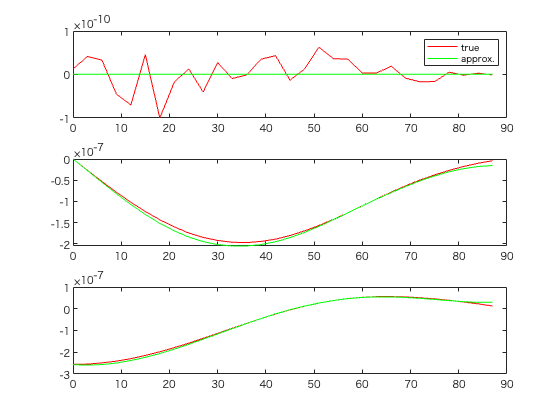

figure
tiledlayout(3,1),nexttile
plot(rad2deg(thetaN), srpCsTrue(:,1),'r'), hold on
plot(rad2deg(thetaN), srpCsApprox(:,1),'g')
legend('true','approx.')
nexttile
plot(rad2deg(thetaN), srpCsTrue(:,2),'r'), hold on
plot(rad2deg(thetaN), srpCsApprox(:,2),'g')
nexttile
plot(rad2deg(thetaN), srpCsTrue(:,3),'r'), hold on
plot(rad2deg(thetaN), srpCsApprox(:,3),'g')